# Examples of Symmetric Filtertypes

Goal is to determine :

- a_k

- b_k

- N

- M

We only care about FIR filters:

- a_k=1

- sum(b_0+b^n*z^-n)=H(z)

- h[n]=b_0...b_N

- FIR of N-th order has N+1 coefficients and is equal to it's impulse response

Symmetry:

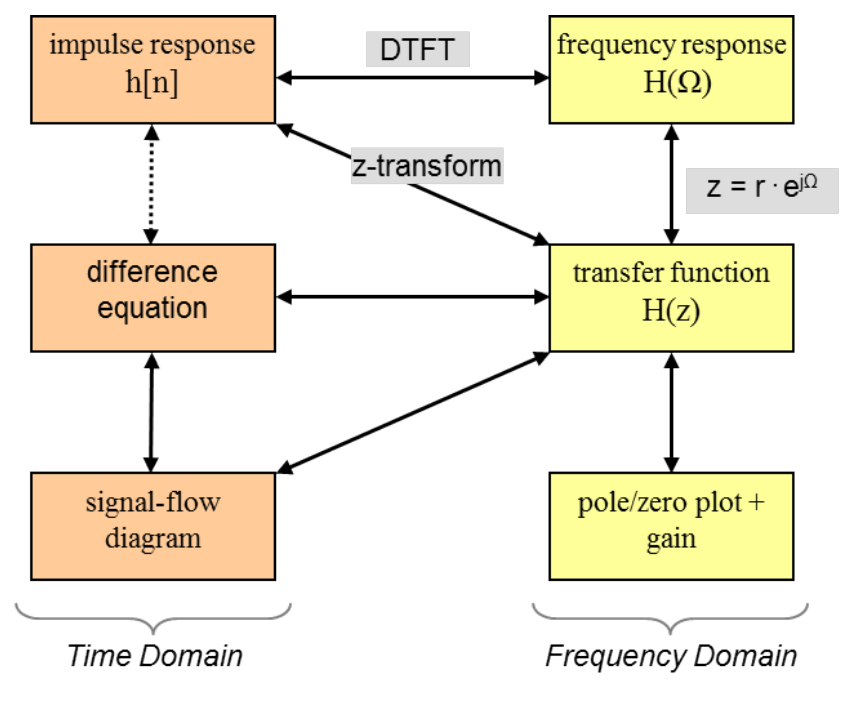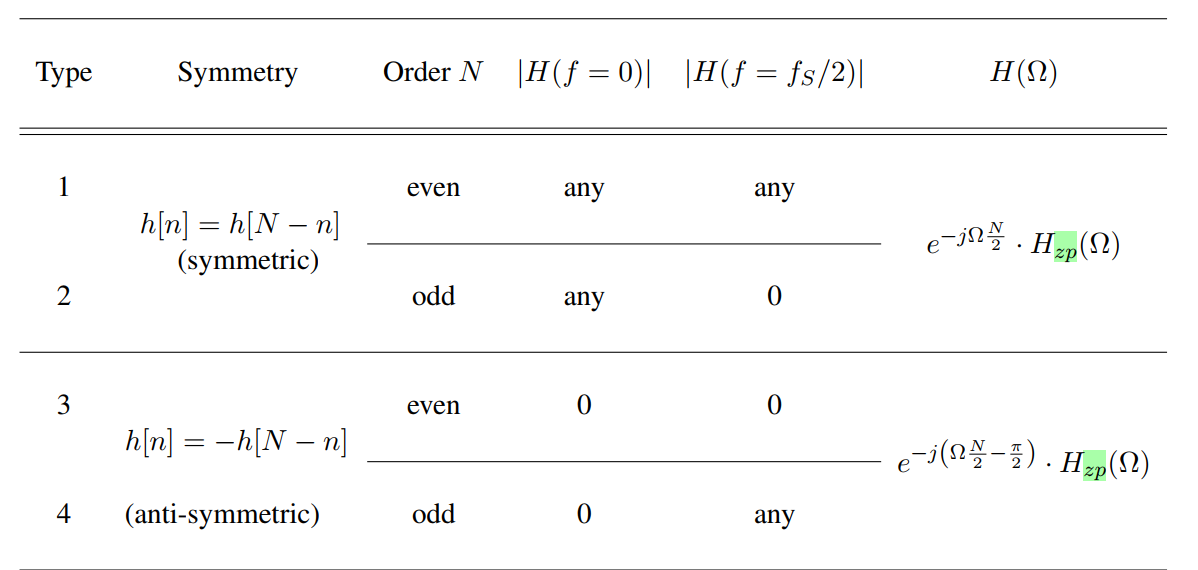

clear all;
close all;
clc;

## Signal 

**Definition**

n=[0:1:15]; %meaning fs=16[Hz]
Ts=1/length(n);
fs=1/Ts;

x_1n=sin(2*pi*1*n/length(n));% 1*fs/16 = 1 Hz
x_2n=sin(2*pi*2*n/length(n));% 2*fs/16 = 2 Hz
%x_3n=sin(2*pi*3*n/length(n));% 3*fs/16 = 3 Hz
%x_4n=sin(2*pi*7*n/length(n));% 7*fs/16 = 7 Hz
%x_ges=x_1n+x_2n+x_3n+x_4n;
x_ges=x_1n+x_2n;

stem(x_ges);

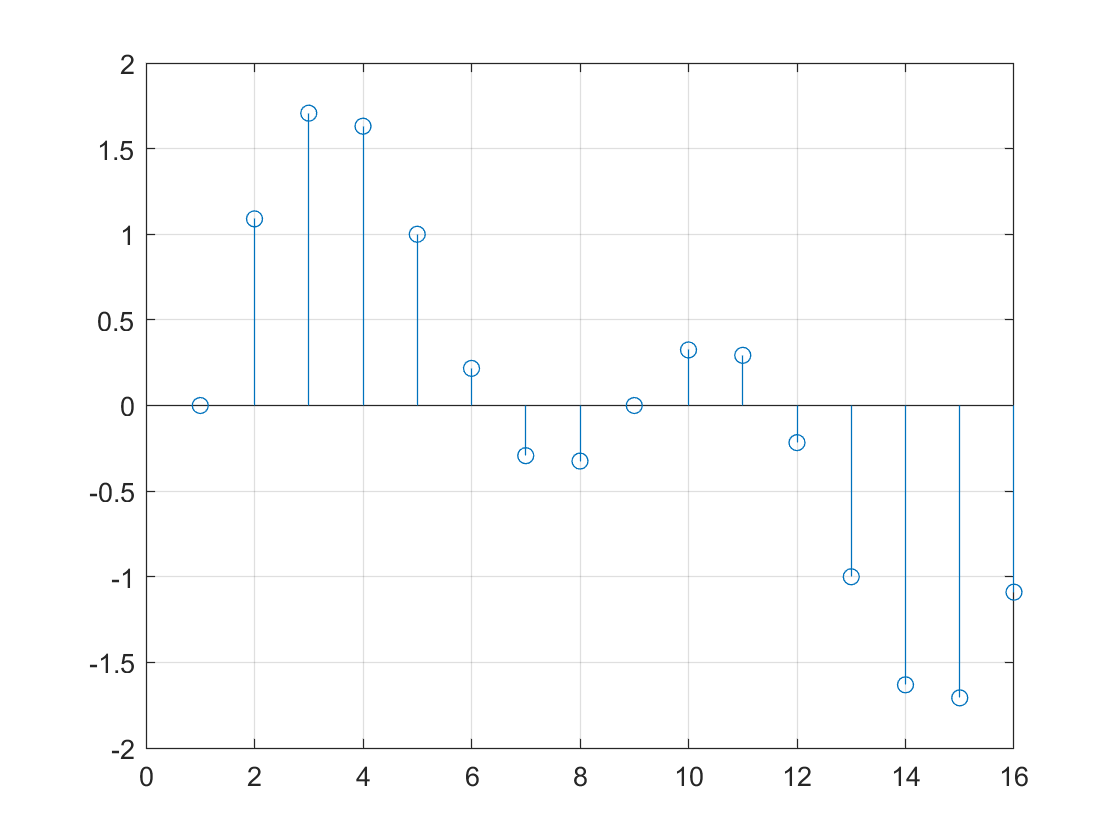

grid on;

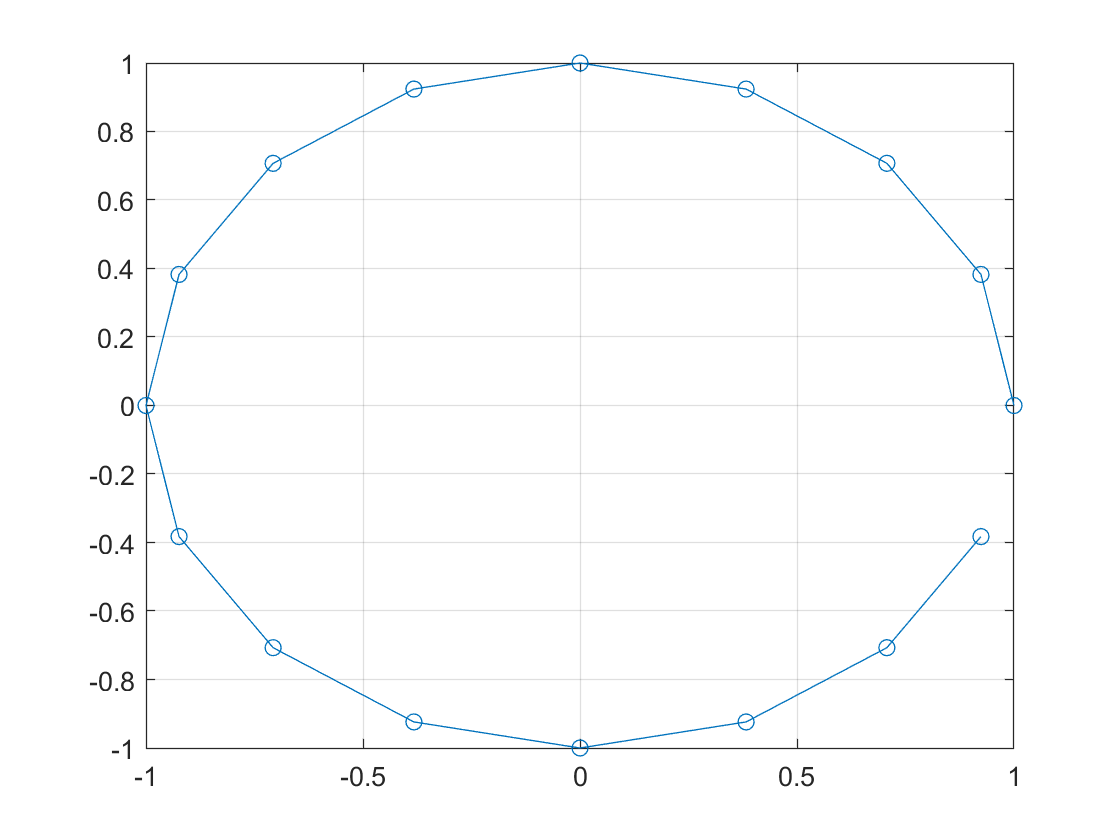


%Omgea=f/fs, weshalb ist bei pi die maximalfrequenz? 
%ist das weil unser signal im(exp()) ist? und das ist ein sin und ein sin
%ist 0 bei pi?
%plot the unit circle
a=exp(j*2*pi*n/length(n));
plot(real(a),imag(a),'-o')
grid on;

**Frequency** of Signal

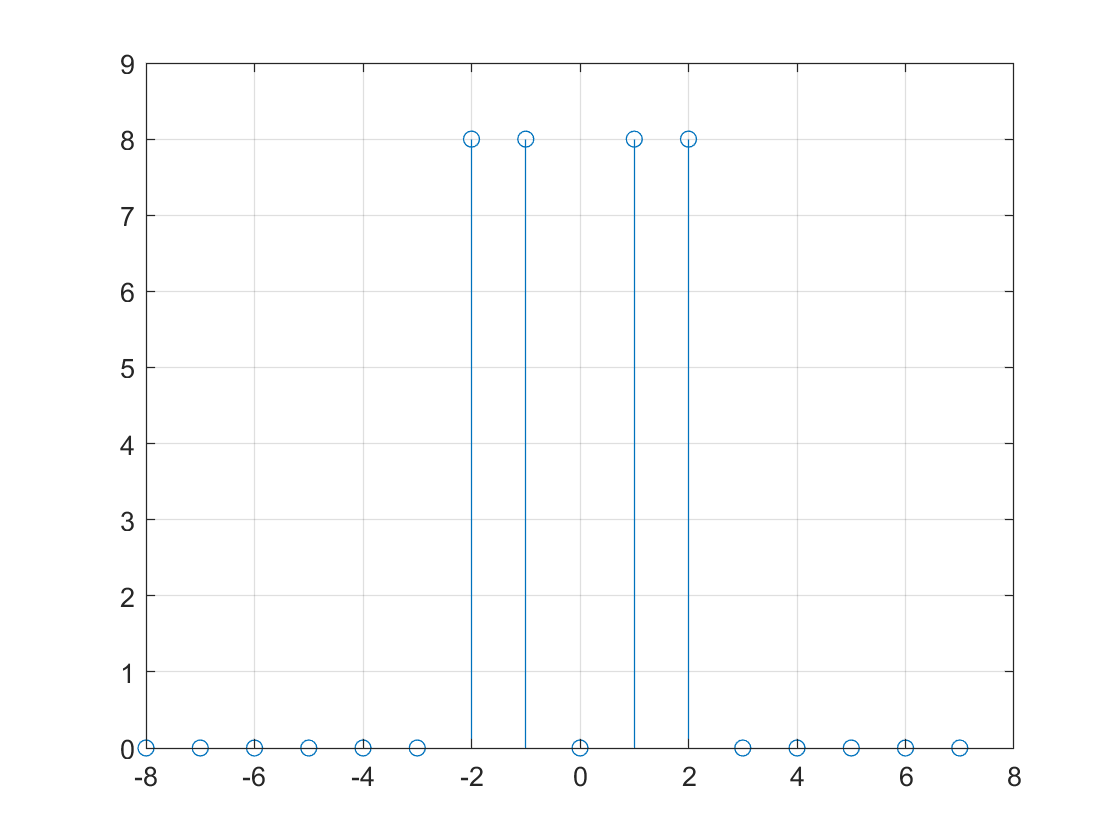

X_f=fft(x_ges);
stem([-8:1:7],fftshift(abs(X_f)))
grid on;

## FIR Filtertypes 

**Impulseresponse:**

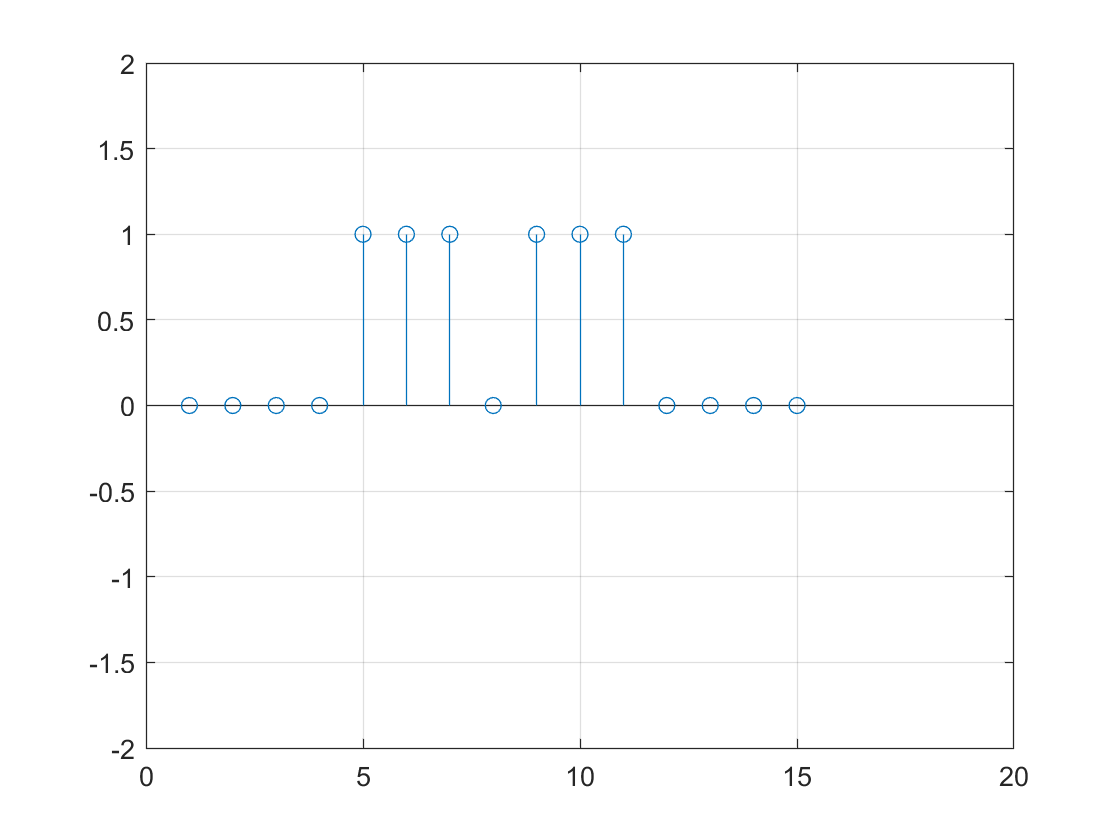

% b0*z^-0 + b1*z^-1 + b2*z^-2 + b3*z^-3 + b4*z^4...
% this is actually the difference equation?
%h_n=[1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]; %Impulseresponse kann nicht sein h_n=[1 0 0 0 0 ... -1];
if false
    %anti symmetric even
    h_n=[1 0 0 0 0 0 0 0 0 0 0 0 0 0 -1];
elseif false
    %symmetric even
    h_n=[1 0 0 0 0 0 0 0 0 0 0 0 0 0 1];
elseif false
    %anti symmetric odd
    h_n=[1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 -1];
elseif false
    %symmetric odd
    h_n=[1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1];
elseif false
    %delay of 2 Ts
    h_n=[0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
elseif false
    %delay of 7 Ts
    h_n=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0];
elseif false
    %symmetric even TP
    h_n=[1 1 0 0 0 0 0 0 0 0 0 0 0 1 1];
elseif false
%symmetric even BP
    h_n=[0.1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.1];
elseif false
%symmetric even LP
    h_n=[0.1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.1];
elseif true
%symmetric even bs
    h_n=[0 0 0 0 1 1 1 0 1 1 1 0 0 0 0];

end
stem(h_n)
grid on; 
axis([0 20 -2 2]);

numerator=h_n;
denumerator=1;

**Transferfunction**

% (1 + z^-2 + z^-4) / 1
H_z=tf(numerator,denumerator,Ts,'Variable','z^-1'); 
H_Omega=fft(h_n);

**FrequencyResponse**

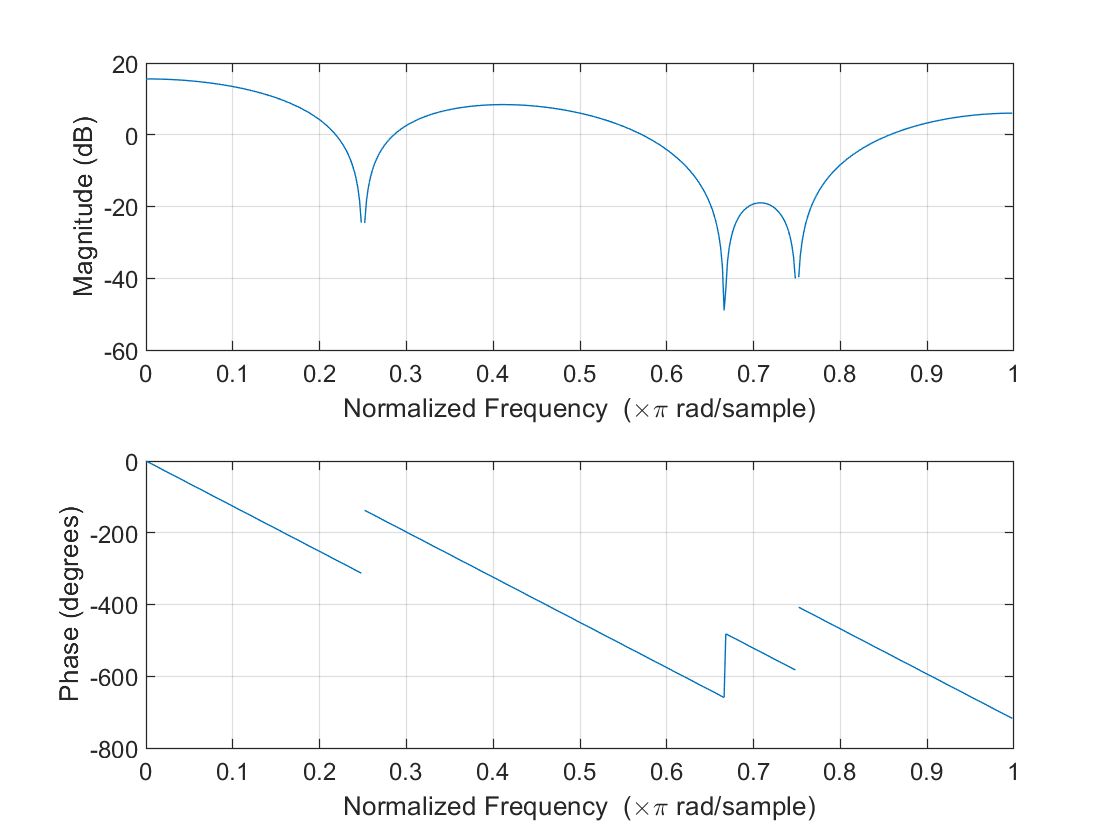

H=freqz(h_n,16,'whole',16);
freqz(h_n)

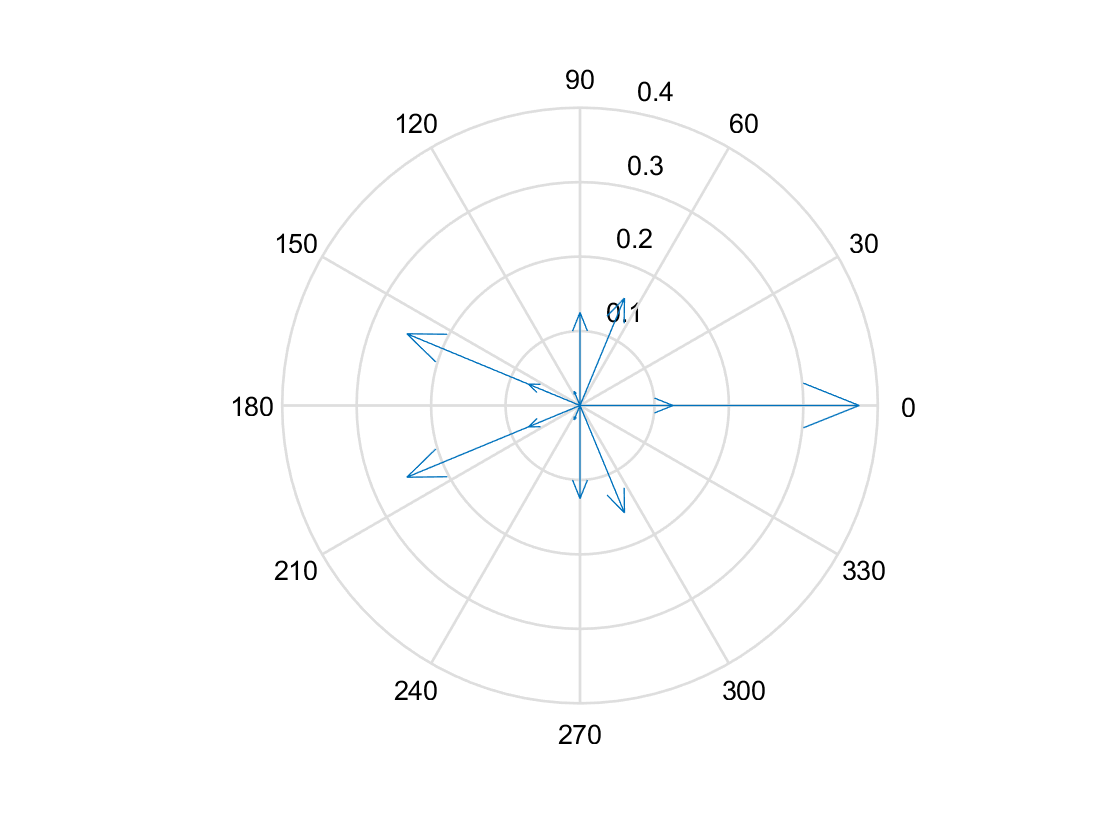

compass(H)

**Pole Zero Plot**

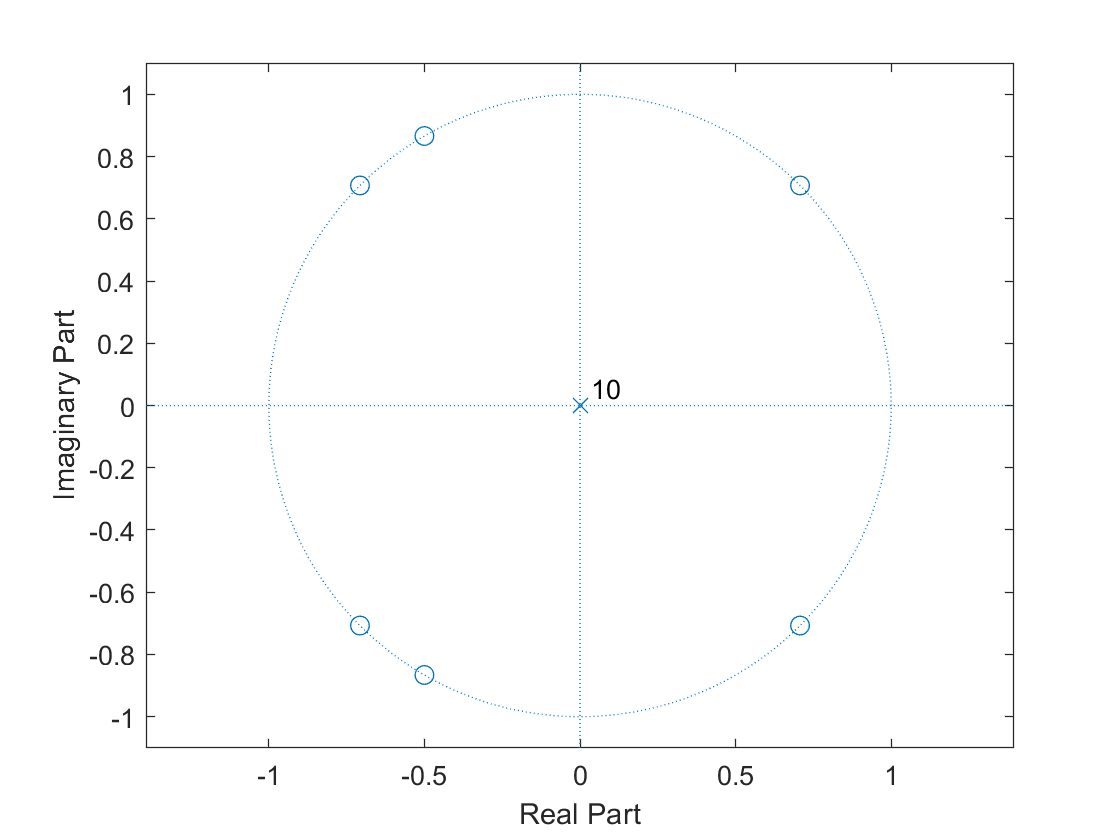

zplane(numerator, denumerator)


%signalflowdiagramm can be created with filterDesigner

**Signalflowdiagramm**, same picter times 16 or so....(z^-1 not z^-2)

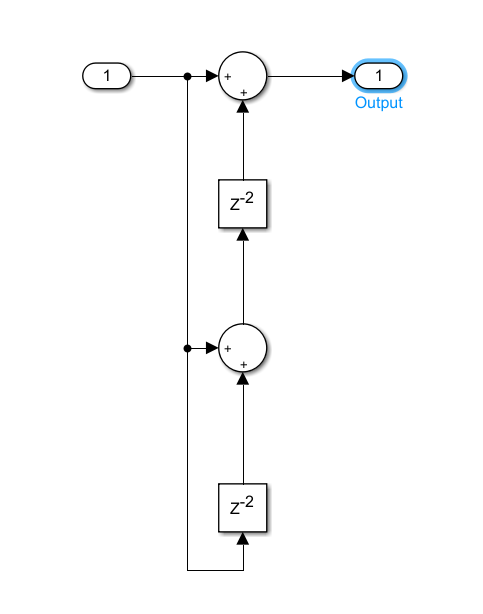

**Difference Equation**

% b0*z^-0 + b1*z^-1 + b2*z^-2 + b3*z^-3 + b4*z^4
% y[n]=b0*x[n-0]+b1*[n-1]+b1*[n-2]+b1*[n-3]+b1*[n-4]
%still false i guess!
y_n= [ sum(h_n(1)*circshift([x_1n zeros(1,1 )],0)) sum(h_n(2)*circshift([x_1n zeros(1,1 )],1)) sum(h_n(3)*circshift([x_1n zeros(1,1 )],2)) sum(h_n(4)*circshift([x_1n zeros(1,1 )],3)) sum(h_n(5)*circshift([x_1n zeros(1,1 )],4))] 

y_n =      0     0     0     0     0


So what Frequencies will we dampen? 

apparently de frequencies at 0.3*Omega and 0.6*Omega which is

0.3*2*pi*f/fs resp. 0.6*2*pi*f/fs which is

f_k=[0:1:15]

f_k =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


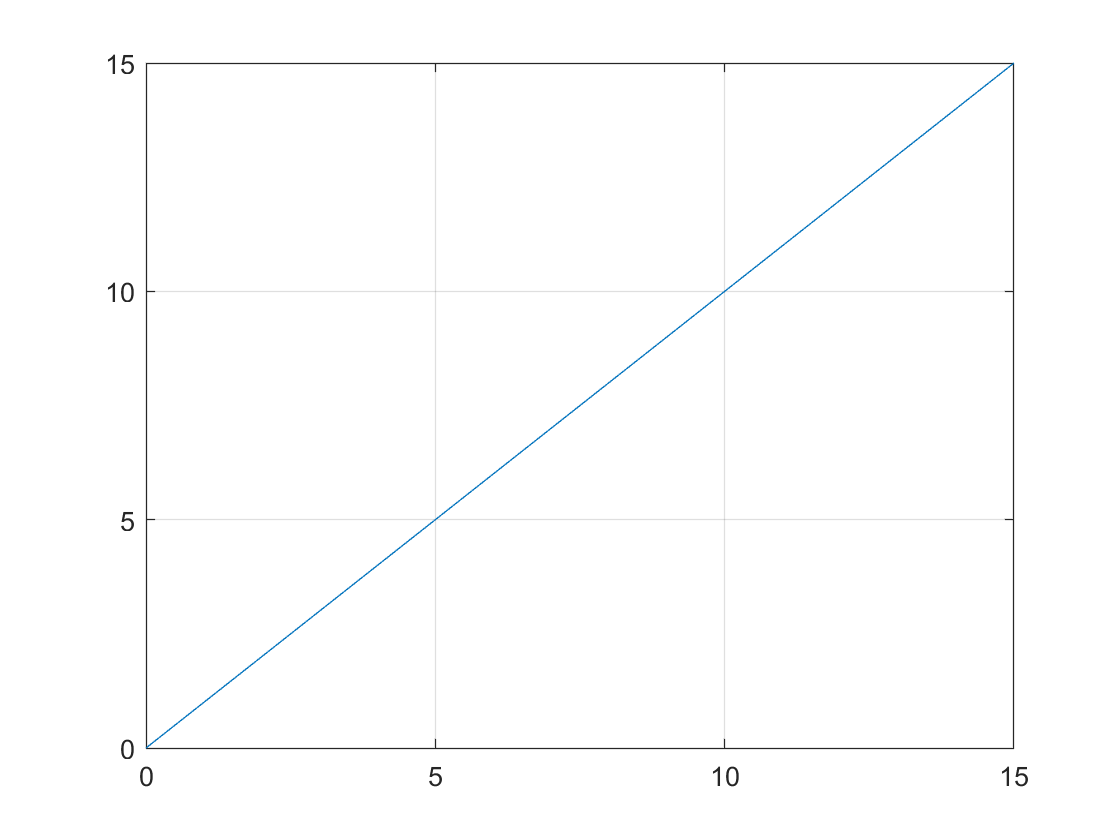

plot([0:1:15],f_k)
grid on;

## Apply filter:

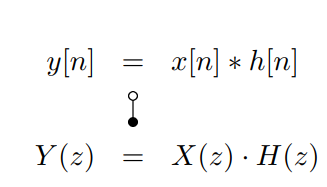

**Timespace** = Convolution

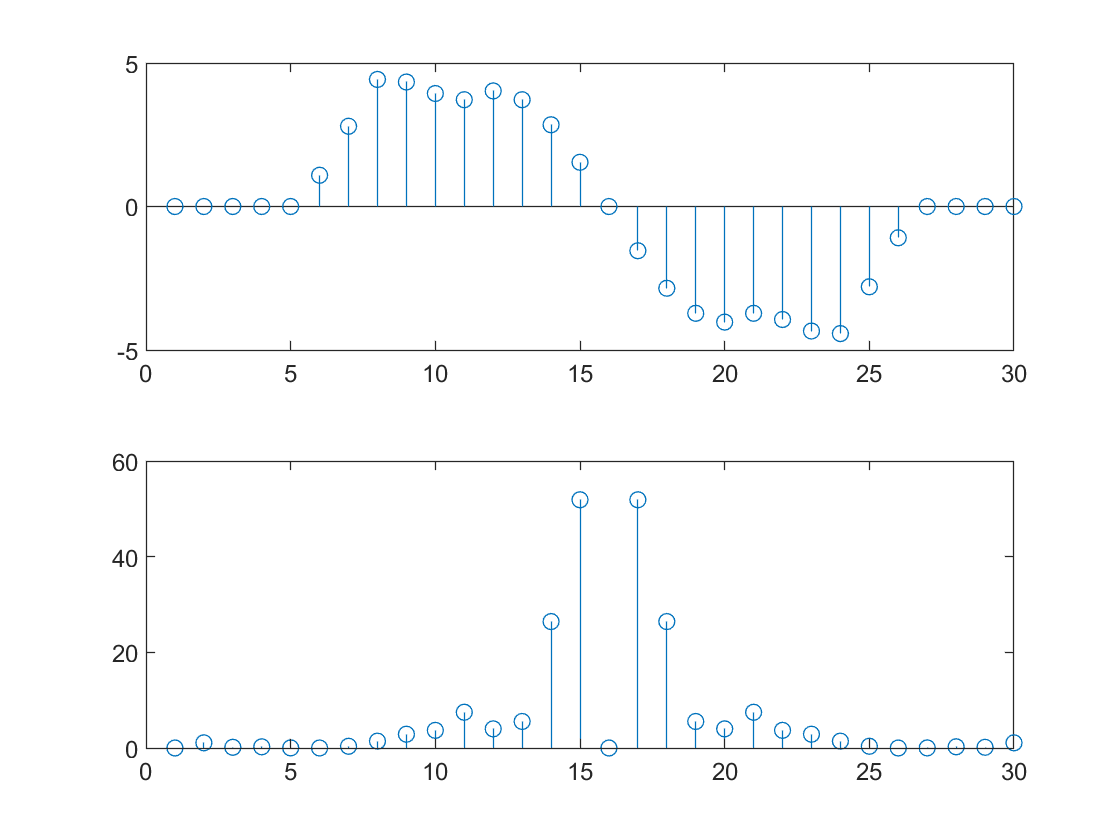

y_ges_t=conv(x_ges,h_n);
subplot(2,1,1)
stem(y_ges_t)
subplot(2,1,2)
stem(fftshift(abs(fft(y_ges_t))))

**Frequency Space** = Multiplication

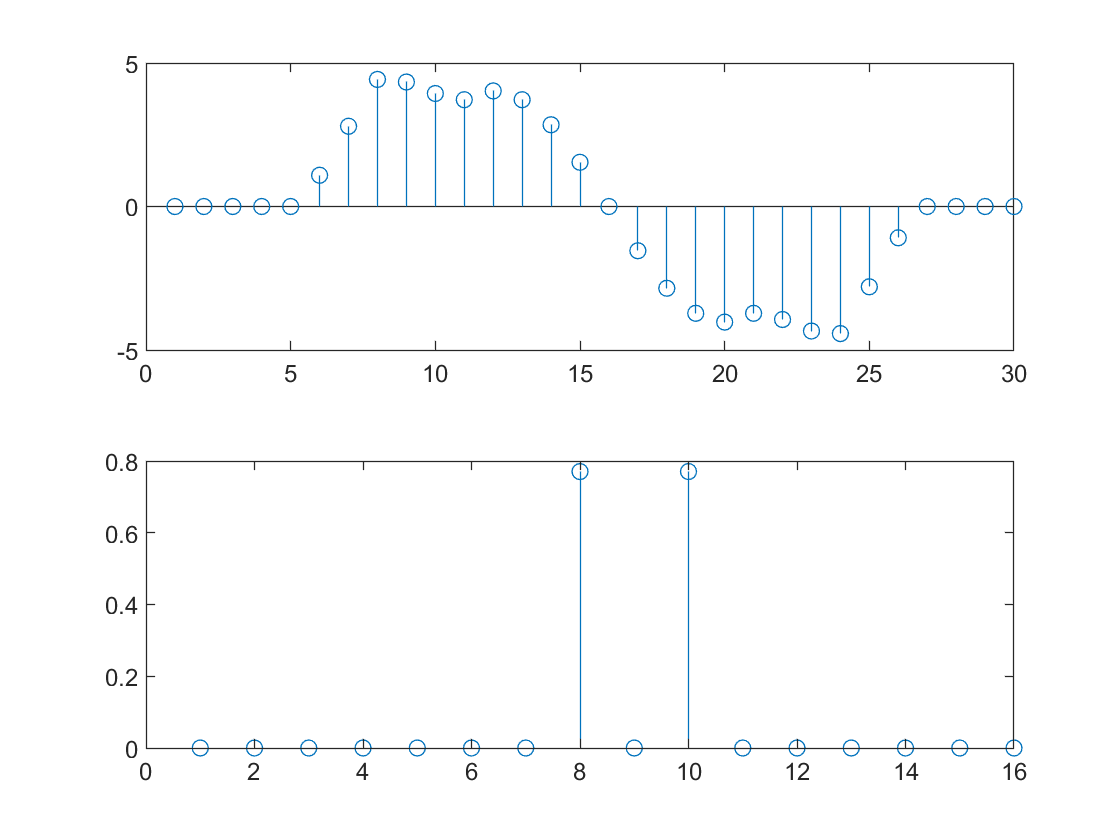

y_ges_f=X_f.*H';
stem(fftshift(y_ges_f));

Multiplication with Transferfunction

%y_ges_z=X_f*

## Questions:

- How can I apply my filter without convolution? how do i get my amplituderesponse? freqz?

- Y(Z)=X(Z)*H(Z) what about H(Omega), how can i utilize my amplitude response? 

- How do i get my H(z)

- To which of my frequencies correspond the zeros on my pz plot?

- Why is the height of my spectrum 8? does  it correspond to N/2? Same for last spectrum.

- Why is there a difference between my zeropoles on the pzplot and my expecte poles on the unitcircle?

- Why does my sine look like that?

- Regarding the normalized frequency: if fs is the largest frequency it corresponds to one roundtrip around the unit circle, so if fs=16, the lowest frequency is 1/16 on the unit circle, right? 

- Why isn't there a plot at 0 on the p/z plot?

- Why is my amplitude so huge?

- fs^-1=f_0

- What is H_zp in script? links phase, rechts reelle verstärkung **(solved, siehe aufnahme)**

- was repräsentiert index 1 2 3 4 in h[n]? sollte das nicht ganzzahlige vielfache von f_k sein?

- I don't understand arrowlength e.g. why does the arrow at frequency 0 (real axis, have the biggest length?

- how do i calculate the delay in seconds from the groupdelay, phase?

- regarding filters, what does even and odd mean? 